# ELEC 300 Assignment 8

% Symbolic math toolbox, symunit.
format compact
u = symunit;

a = -20

a = -20

A = [1 2 3; 4 5 6; 5 3 4;]

A =      1     2     3
     4     5     6
     5     3     4


latex(sym(A))

ans = '\left(\begin{array}{ccc} 1 & 2 & 3\\ 4 & 5 & 6\\ 5 & 3 & 4 \end{array}\right)'


BC =2

BC = 2


$$Anime= '\left(\begin{array}{ccc} 1 & 2 & 3\\ 4 & 5 & 6\\ 5 & 3 & 4 \end{array}\right)'$$
 

## Problem 1 --- 18.18 Nillison Riddel 5th edition 

Find the s-domain expressions for the z parameters of the two-port circuit shown in Fig. P18.18

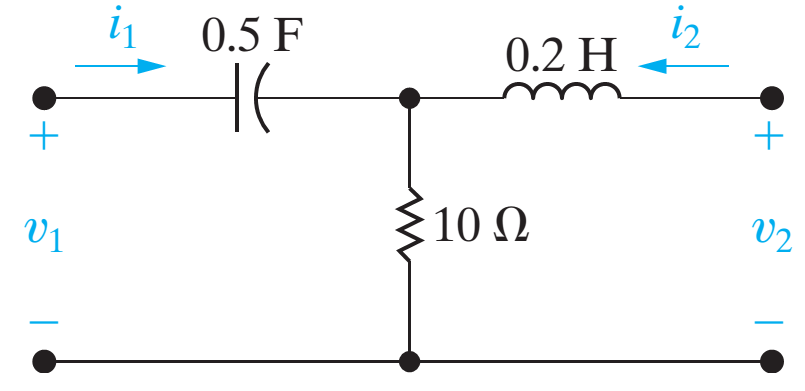

- $z_{11}$ is the impedance seen looking into port 1 when port 2 is open.

- $z_{12}$ is a transfer impedance. It is the ratio of the port 1 voltage to the port 2 current when port 1 is open.

- $z_{21}$ is a transfer impedance. It is the ratio of the port 2 voltage to the port 1 current when port 2 is open.

- $z_{22}$ is the impedance seen looking into port 2 when port 1 is open.

syms s
z11 = (10 + 1/(0.5*s))*u.Ohm

$$z11 = \left(\frac{2}{s}+10\right)\,\Omega$$

z21 = 10*u.Ohm

$$z21 = 10\,\Omega$$

z12 = 10*u.Ohm

$$z12 = 10\,\Omega$$

z22 = (0.2*s+10)*u.Ohm

$$z22 = \left(\frac{s}{5}+10\right)\,\Omega$$

## Problem 2 --- 19.26 Alexander sixth edition

19.26 Calculate [y] for the two-port in Fig. 19.85.

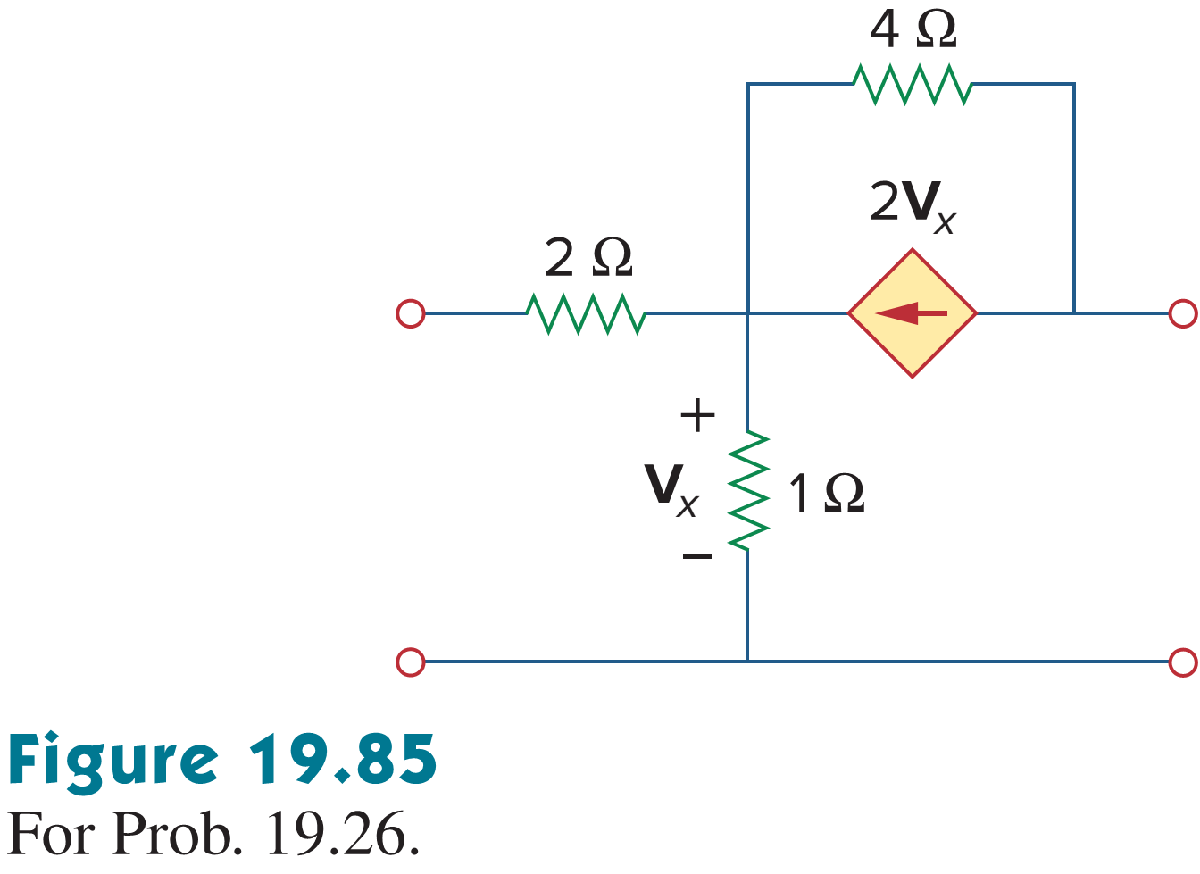


$$y_{11}= \frac{I_1}{V_1} \vert_{V_2=0} S, \quad 
y_{21}= \frac{I_2}{V_1} \vert_{V_2=0} S,$$



$$y_{12} = \frac{I_1}{V_2} \vert_{V_1=0} \ S, \quad
y_{22} = \frac{I_2}{V_2} \vert_{V_1=0} \ S$$


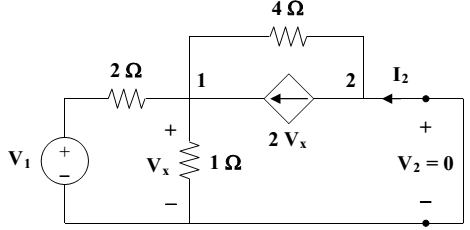

%syms V1 Vx
%p3eqn1 = (V1-Vx)/x+2*Vx == Vx/1+Vx/4
%p3eqn2 = 
y = [1.5 0.5; ...
    -3.5 -1.5]

y =     1.5000    0.5000
   -3.5000   -1.5000


## Problem 3 --- 18.37 Nillison Riddel 5th edition

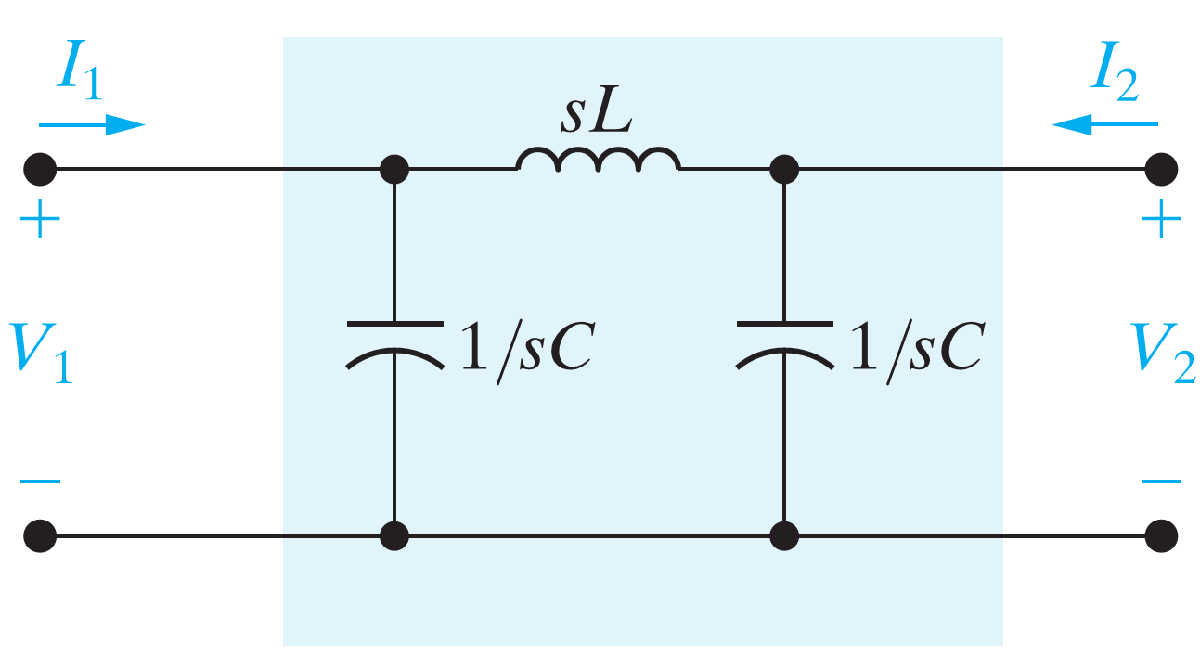

Find the *s*-domain expressions for the *g *parameters of the circuit in Fig. P18.37. Port 2 in Fig. P18.37 is terminated in a resistance of $500 \Omega$ and port 1 is driven by a step voltage source $v_1(t)=4u(t) V.$ Find $v_2(t)$ for $t > 0$ if C = 32 nF and L = 50 mH.


$$g_{11}= \frac{I_1}{V_1} \vert_{I_2=0} \ S, \quad
g_{12}= \frac{I_1}{I_2} \vert_{V_1=0}, $$



$$g_{21}= \frac{V_2}{V_1} \vert_{I_2=0}, \quad
g_{22}= \frac{V_2}{I_2} \vert_{V_1=0} \quad \Omega$$


syms C L
% Find g11
p3z111 = s*L+1/(s*C)

$$p3z111 = L\,s+\frac{1}{C\,s}$$

p3z11 = (1/(s*C)*p3z111)/(1/(s*C)+p3z111)

$$p3z11 = \frac{L\,s+\frac{1}{C\,s}}{C\,s\,\left(L\,s+\frac{2}{C\,s}\right)}$$

p3z11 = simplify(p3z11)

$$p3z11 = \frac{C\,L\,s^{2}+1}{C\,s\,\left(C\,L\,s^{2}+2\right)}$$

p3g11 = 1/p3z11

$$p3g11 = \frac{C\,s\,\left(C\,L\,s^{2}+2\right)}{C\,L\,s^{2}+1}$$

p3g11 = simplify(p3g11)

$$p3g11 = \frac{C\,s\,\left(C\,L\,s^{2}+2\right)}{C\,L\,s^{2}+1}$$

% factor(p3g11)

% Find g21
p3g21 = 1/(s*C)/(s*L+1/(s*C))

$$p3g21 = \frac{1}{C\,s\,\left(L\,s+\frac{1}{C\,s}\right)}$$

p3g21 = simplify(p3g21)

$$p3g21 = \frac{1}{C\,L\,s^{2}+1}$$


% Find g12 
ZC = 1/(s*C)

$$ZC = \frac{1}{C\,s}$$

ZL = s*L

$$ZL = L\,s$$

ZT = ZC + ZL

$$ZT = L\,s+\frac{1}{C\,s}$$

p3g12 = ZC/ZT% Using current divider 

$$p3g12 = \frac{1}{C\,s\,\left(L\,s+\frac{1}{C\,s}\right)}$$

% I1 and I2, (ZT / Zx)^{-1} = Zx / ZT
% Find g22, using sL || 1/sC
p3g22 = ZL*ZC/(ZL+ZC)

$$p3g22 = \frac{L}{C\,\left(L\,s+\frac{1}{C\,s}\right)}$$

p3g22 = simplify(p3g22)

$$p3g22 = \frac{L\,s}{C\,L\,s^{2}+1}$$

## Problem 4 --- 19.70* Alexander sixth edition

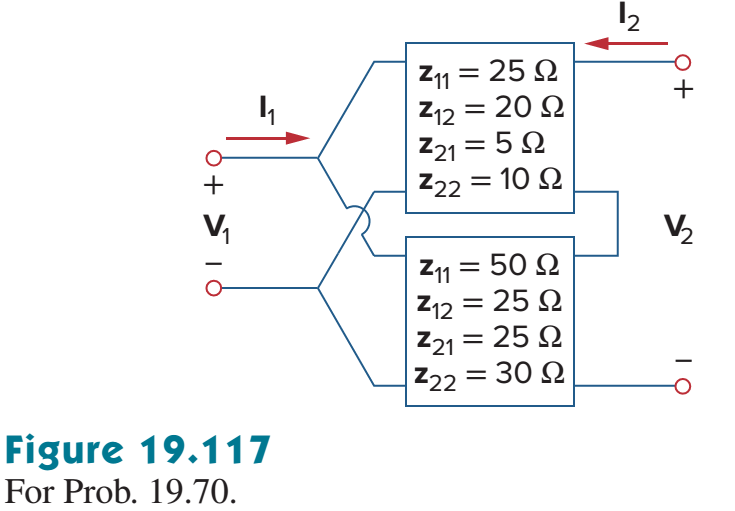

Using the Conversion of two-port parameters table,

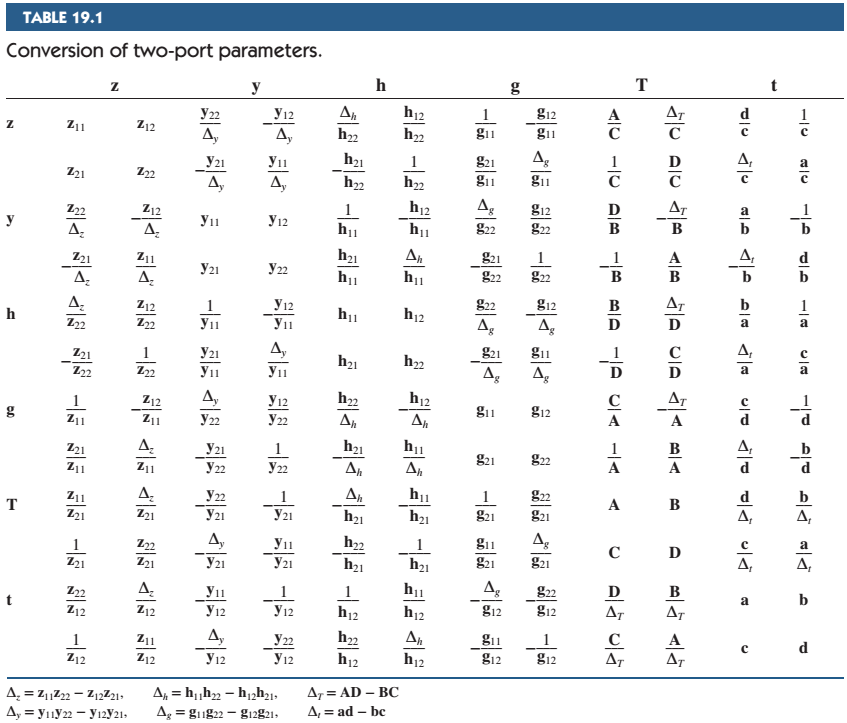

za = [25 20; ...
      5  10]

za =     25    20
     5    10


zb = [50 25; ...
      25 30]

zb =     50    25
    25    30


ga = [1/za(1,1) -za(1,2)/(za(1,1)); ...
      za(2,1)/(za(1,1)) det(za)/(za(1,1))]

ga =     0.0400   -0.8000
    0.2000    6.0000


gb = [1/zb(1,1) -zb(1,2)/(zb(1,1)); ...
      zb(2,1)/(zb(1,1)) det(zb)/(zb(1,1))]

gb =     0.0200   -0.5000
    0.5000   17.5000


g  = ga+gb

g =     0.0600   -1.3000
    0.7000   23.5000


## Problem 5 --- 18.7 Nillison Riddel fifth edition

18.7 Select the values of and in the circuit in Fig. P18.7 so that  $h_{11}= 4 \Omega$, $h_{12}= 0.8$,


$$h_{21}= -0/8  \text{ and } h_{22}=0.14 S$$


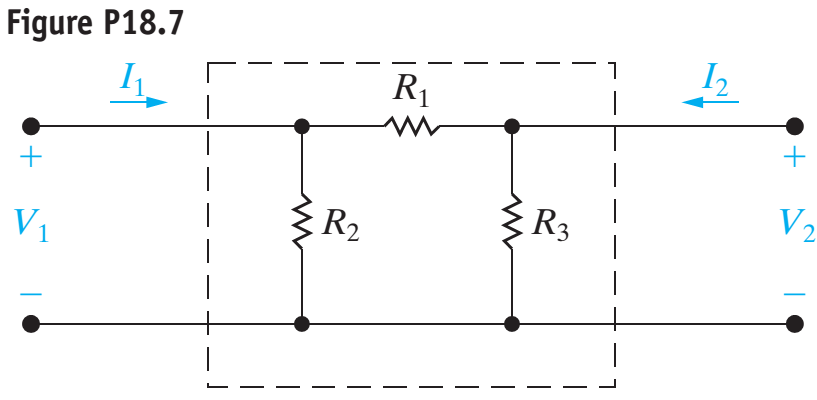

syms R1 R2 R3

% Use values in h11, and h21 for 2 equations
p5eqn1=R1*R2/(R1+R2)==4*u.Ohm

$$p5eqn1 = \frac{R_{1}\,R_{2}}{R_{1}+R_{2}}=4\,\Omega$$

p5eqn2=-R2/(R1+R2)==-0.8

$$p5eqn2 = -\frac{R_{2}}{R_{1}+R_{2}}=-\frac{4}{5}$$

p5ans1 = solve([p5eqn1,p5eqn2],[R1,R2])

p5ans1 = struct with fields:
    R1: [1×1 sym]
    R2: [1×1 sym]

R1num = p5ans1.R1

$$R1num = 5\,\Omega$$

R2num = p5ans1.R2

$$R2num = 20\,\Omega$$


p5eqn3 = 1/((R3*(R2num+R1num))/(R3+R2num+R1num)) == 0.14/u.Ohm 

$$p5eqn3 = \frac{R_{3}+25\,\Omega }{25\,R_{3}}\,\frac{1}{\Omega }=\frac{7}{50}\,\frac{1}{\Omega }$$

R3num = solve([p5eqn3],[R3])

$$p5ans2 = 10\,\Omega$$

## Problem 6 --- 18.30 Nillision Riddel 5th edition 

18.30 The g parameters for the two-port circuit in Fig. P18.30 are

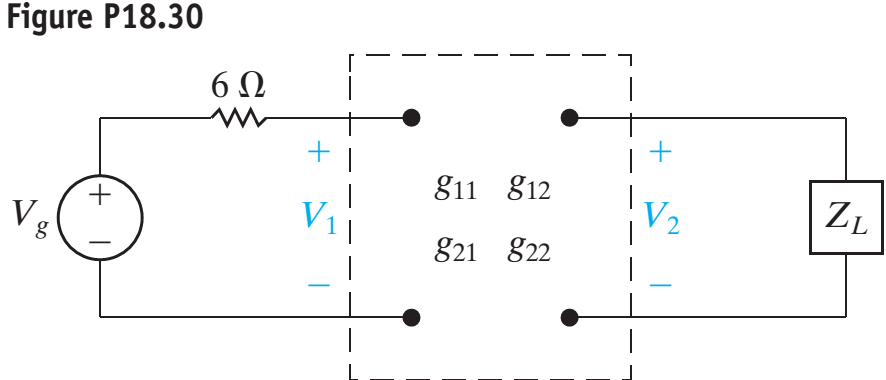

## Testing

x = [1 2 3 4]'

x =      1
     2
     3
     4


y = [4 5 6 7]'

y =      4
     5
     6
     7


% I presume that the matlab people are working on
% matlab package that can interpret all the matlab commands
% when that happens that will be fairly good.
table(x,y)

ans = 4×2 table
    x    y
    _    _
    1    4
    2    5
    3    6
    4    7